# Train PG Agent to Balance Cart-Pole System

This example shows how to train a policy gradient (PG) agent to balance a cart-pole system modeled in MATLAB®. For more information on PG agents, see [Policy Gradient Agents](docid:rl_ug#mw_f423c6cd-035f-4831-9f2c-3585ea36d379). 

For an example on training a PG agent with baseline, see [Train PG Agent with Baseline to Control Double Integrator System](docid:rl_ug#mw_58b9b648-65ce-495a-aeb7-62f089690a5a) example. 

## Cart-pole MATLAB Environment

The reinforcement learning environment for this example is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pendulum stand upright without falling over.

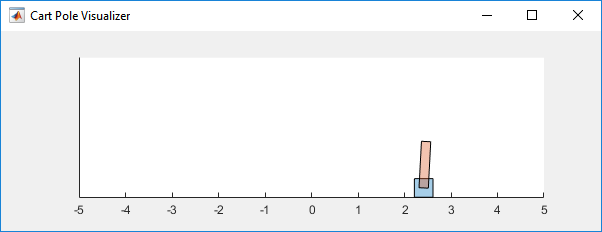

For this environment:

- The upward balanced pendulum position is `0` radians, and the downward hanging position is `pi` radians

- The pendulum starts upright with an initial angle of +/- 0.05 radians

- The force action signal from the agent to the environment is from -10 to 10 N

- The observations from the environment are the position and velocity of the cart, the pendulum angle, and its derivative

- The episode terminates if the pole is more than 12 degrees from vertical, or the cart moves more than 2.4 m from the original position

- A reward of +1 is provided for every time step that the pole remains upright. A penalty of -5 is applied when the pendulum falls.

For more information on this model, see [Load Predefined Control System Environments](docid:rl_ug#mw_537f0c6d-2ccd-454b-95fa-3ee88ece74aa).

## Create Environment Interface

Create a predefined environment interface for the pendulum.

env = rlPredefinedEnv("CartPole-Discrete")

env =   CartPoleDiscreteAction with properties:

                  Gravity: 9.8000
                 MassCart: 1
                 MassPole: 0.1000
                   Length: 0.5000
                 MaxForce: 10
                       Ts: 0.0200
    ThetaThresholdRadians: 0.2094
               XThreshold: 2.4000
      RewardForNotFalling: 1
        PenaltyForFalling: -5
                    State: [4×1 double]


The interface has a discrete action space where the agent can apply one of two possible force values to the cart, -10 or 10 N.

Obtain the observation and action information from the environment interface. 

obsInfo = getObservationInfo(env);      % dimensao das observacoes, posicao do carrinho, velocidade do carrinho, angulo do pendulo, velocidade do pendulo
numObservations = obsInfo.Dimension(1); % quantidade de observacoes
actInfo = getActionInfo(env);           % elements tem duas acoes possiveis, dimensao da acao é 1

Fix the random generator seed for reproducibility.

rng(0)

## Create PG agent

A PG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input (the observation) and one output (the action). The output size actor network is 2 since the agent can apply 2 possible actions, 10 or -10. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','state') % nao confundir com entrada de imagem, 
                                                                                 % é só um aproveitamento desse tipo de camada de entrada, o matlab 2020b tem uma camada melhor para isso 
                                                                                 % esta declarando normalizacao como nenhuma, pq o padrão dessa camada é normalizar os valores de entrada pela média, e não precisamos disso aqui
                                                                                 % da para criar a propria camada com o tutorial Define Custom Deep Learning Layer with Learnable Parameters
    fullyConnectedLayer(2,'Name','fc')                                           % duas acoes possiveis
    softmaxLayer('Name','actionProb')                                            % sai o indice da acao com maior valor
    ];

Specify options for the actor representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

actorOpts = rlRepresentationOptions('LearnRate',1e-2,'GradientThreshold',1);    % opcoes para o objeto actor, taxa de aprendizado e limite para o gradiente em 1, limitando o quando os parametros da rede podem mudar em cada interacao

Create the actor representation using the specified deep neural network and options. You must also specify the action and observation information for the critic, which you already obtained from the environment interface. For more information, see [`rlStochasticActorRepresentation`](docid:rl_ref#mw_3f02b852-372d-4db5-b791-487e4a0afdfa).

actor = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'state'},actorOpts);

Then, create the agent using the specified actor representation, and the default agent options. For more information, see [`rlPGAgent`](docid:rl_ref#mw_f4fa01ba-308e-436c-93c2-8bdf140eb6d8).

agent = rlPGAgent(actor);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training episode for at most 1000 episodes, with each episode lasting at most 200 time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than 195 over 100 consecutive episodes. At this point, the agent can balance the pendulum in the upright position.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 1000, ...
    'MaxStepsPerEpisode', 200, ...
    'Verbose', false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',195,...
    'ScoreAveragingWindowLength',100); 

The cart-pole system can be visualized with using the `plot` function during training or simulation.

plot(env)

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('MATLABCartpolePG.mat','agent');
end

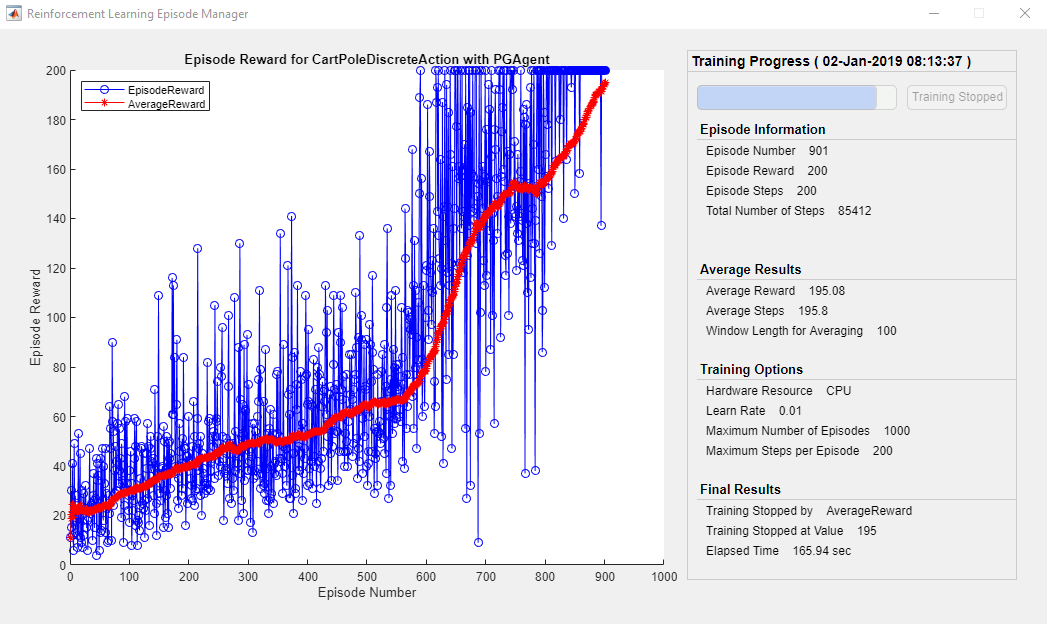

## Simulate PG Agent

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf). The agent can balance the cart-pole even when simulation time increases to 500.

simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);
totalReward = sum(experience.Reward)

totalReward = 500

*Copyright 2019 The MathWorks, Inc.*